# Create Rotational Transformation Matrix from Axis-Angle Representation of Rotation in Space

## obvious solution

% https://de.mathworks.com/help/robotics/ref/axang2rotm.html

function doesn't accept syms data type

## Definition

syms C ga B f_WSTrad phi
% C = f_WSTrad * B
phi = -C+ga;

Rotation of angle phi around z-axis

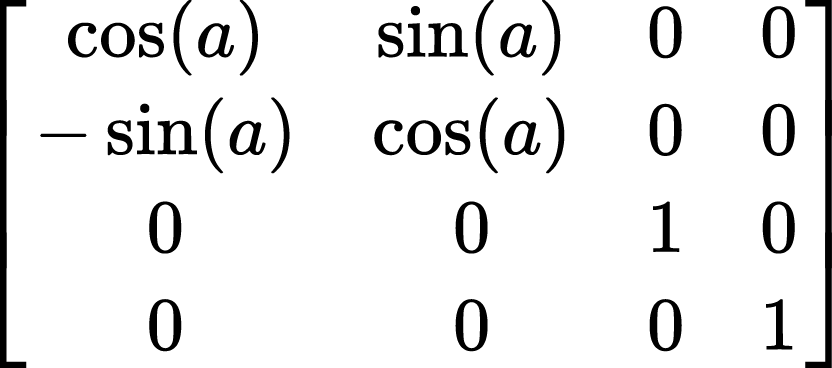

### Hardcode

R_Cga= [cos(phi) -sin(phi) 0 0; sin(phi) cos(phi) 0 0; 0 0 1 0; 0 0 0 1]

$$R\_Cga = \left(\begin{array}{cccc} \cos\left(C-\mathrm{ga}\right) & \sin\left(C-\mathrm{ga}\right) & 0 & 0\\ -\sin\left(C-\mathrm{ga}\right) & \cos\left(C-\mathrm{ga}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### axang2rotm

ax = [0, 0, 1; 1, 0, 0];
ang = [phi;phi];
rotm = axang2rotm(ax,ang)

$$\left(\begin{array}{ccc} \cos\left(C-\mathrm{ga}\right) & \sin\left(C-\mathrm{ga}\right) & 0\\ -\sin\left(C-\mathrm{ga}\right) & \cos\left(C-\mathrm{ga}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(C-\mathrm{ga}\right) & \sin\left(C-\mathrm{ga}\right)\\ 0 & -\sin\left(C-\mathrm{ga}\right) & \cos\left(C-\mathrm{ga}\right) \end{array}\right)$$

### Using a dedicated function

R_Cga = dim4(axang2rtm([0,0,1],phi),2,'forward')

$$R\_Cga = \left(\begin{array}{cccc} \cos\left(C-\mathrm{ga}\right) & \sin\left(C-\mathrm{ga}\right) & 0 & 0\\ -\sin\left(C-\mathrm{ga}\right) & \cos\left(C-\mathrm{ga}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Using a rotated vector

kvec = [0;0;1];     % unit vector of rotation axis
vvec = [1;0;0];     % unit vector of direction in R^3
vrot = vvec*cos(phi) + (cross(kvec,vvec))*sin(phi) + kvec*dot(kvec,vvec)*(1-cos(phi))

$$vrot = \left(\begin{array}{c} \cos\left(C-\mathrm{ga}\right)\\ -\sin\left(C-\mathrm{ga}\right)\\ 0 \end{array}\right)$$

R_Cga = vec2rot(vrot,[0,0,1])

$$R\_Cga = \begin{array}{l} \left(\begin{array}{cccc} 1-\frac{{\cos\left(C-\mathrm{ga}\right)}^{2}}{\sigma_{4}\,\left(\sigma_{6}+\sigma_{5}\right)} & \sigma_{1} & -\sigma_{3} & 0\\ \sigma_{1} & 1-\frac{{\sin\left(C-\mathrm{ga}\right)}^{2}}{\sigma_{4}\,\left(\sigma_{6}+\sigma_{5}\right)} & \sigma_{2} & 0\\ \sigma_{3} & -\sigma_{2} & 1-\frac{\frac{{\cos\left(C-\mathrm{ga}\right)}^{2}}{\sigma_{6}+\sigma_{5}}+\frac{{\sin\left(C-\mathrm{ga}\right)}^{2}}{\sigma_{6}+\sigma_{5}}}{\sigma_{4}} & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\cos\left(C-\mathrm{ga}\right)\,\sin\left(C-\mathrm{ga}\right)}{\sigma_{4}\,\left(\sigma_{6}+\sigma_{5}\right)}\\ \sigma_{2}=\frac{\sin\left(C-\mathrm{ga}\right)}{\sqrt{\sigma_{6}+\sigma_{5}}}\\ \sigma_{3}=\frac{\cos\left(C-\mathrm{ga}\right)}{\sqrt{\sigma_{6}+\sigma_{5}}}\\ \sigma_{4}=\frac{\sigma_{6}}{\sigma_{6}+\sigma_{5}}+\frac{\sigma_{5}}{\sigma_{6}+\sigma_{5}}\\ \sigma_{5}={\left|\sin\left(C-\mathrm{ga}\right)\right|}^{2}\\ \sigma_{6}={\left|\cos\left(C-\mathrm{ga}\right)\right|}^{2} \end{array}$$

### Development of private function

function RTM = axang2rtm(ax,ang)
    

Formula found [here](https://en.wikipedia.org/wiki/Rotation_matrix#Rotation_matrix_from_axis_and_angle):

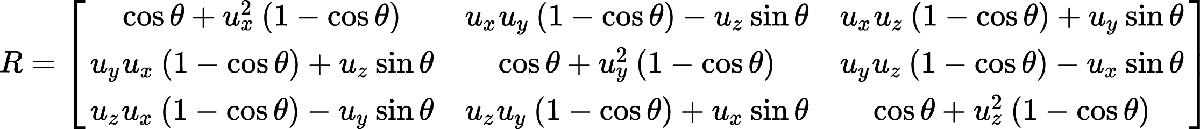

    RTM = [cos(ang) + ax(1)^2*(1-cos(ang)),          ax(1)*ax(2)*(1-cos(ang))-ax(3)*sin(ang), ax(1)*ax(3)*(1-cos(ang)) + ax(2)*sin(ang);...
           ax(2)*ax(3)*(1-cos(ang))+ ax(3)*sin(ang), cos(ang) + ax(2)^2*(1-cos(ang)),         ax(2)*ax(3)*(1-cos(ang)) - ax(1)*sin(ang);...
           ax(3)*ax(1)*(1-cos(ang))-ax(2)*sin(ang),  ax(3)*ax(2)*(1-cos(ang))+ax(1)*sin(ang), cos(ang)+ ax(3)^2*(1-cos(ang))];
end

### Matlab's internal function

function R = axang2rotm( ax, ang )

seperate axis and angle information, because we want to allow for a mix of numeric and sym data types

%AXANG2ROTM Convert axis-angle rotation representation to rotation matrix
%   R = AXANG2ROTM(AXANG) converts a 3D rotation given in axis-angle form,
%   AXANG, to an orthonormal rotation matrix, R. AXANG is an N-by-4
%   matrix of N axis-angle rotations. The first three elements of every
%   row specify the rotation axis and the last element defines the rotation
%   angle (in radians).
%   The output, R, is an 3-by-3-by-N matrix containing N rotation matrices. 
%   Each rotation matrix has a size of 3-by-3 and is orthonormal.
%
%   Example:
%      % Convert a rotation from axis-angle to rotation matrix
%      axang = [0 1 0 pi/2];
%      R = axang2rotm(axang)
%
%   See also rotm2axang

%   Copyright 2014-2018 The MathWorks, Inc.

%#codegen

comment out the validation function

we need to develop our own version of that validation, capable of handling sym data type

% robotics.internal.validation.validateNumericMatrix(axang, 'axang2rotm', 'axang', ...
%     'ncols', 4);

% For a single axis-angle vector [ax ay az theta] the output rotation
% matrix R can be computed as follows:
% R =  [t*x*x + c	  t*x*y - z*s	   t*x*z + y*s
%       t*x*y + z*s	  t*y*y + c	       t*y*z - x*s
%       t*x*z - y*s	  t*y*z + x*s	   t*z*z + c]
% where,
% c = cos(theta)
% s = sin(theta)
% t = 1 - c
% x = normalized axis ax coordinate
% y = normalized axis ay coordinate
% z = normalized axis az coordinate

#### Normalize the axis

default code can't handle sym data type

own code "stolen" from the vec2rot function

% Normalize the axis
% v = robotics.internal.normalizeRows(axang(:,1:3));
v = ax;
v = v/norm(v);

% Extract the rotation angles and shape them in depth dimension
numInputs = size(ang,1);
theta = zeros(1,1,numInputs,'like',ang);
theta(1,1,:) = ang;

% Compute rotation matrices
cth = cos(theta);
sth = sin(theta);
vth = (1 - cth);

% Preallocate input vectors
vx = zeros(1,1,numInputs,'like',ax);
vy = vx;
vz = vx;

% Shape input vectors in depth dimension
vx(1,1,:) = v(:,1);
vy(1,1,:) = v(:,2);
vz(1,1,:) = v(:,3);

% Explicitly specify concatenation dimension
tempR = cat(1, vx.*vx.*vth+cth,     vy.*vx.*vth-vz.*sth, vz.*vx.*vth+vy.*sth, ...
               vx.*vy.*vth+vz.*sth, vy.*vy.*vth+cth,     vz.*vy.*vth-vx.*sth, ...
               vx.*vz.*vth-vy.*sth, vy.*vz.*vth+vx.*sth, vz.*vz.*vth+cth);

R = reshape(tempR, [3, 3, length(vx)]);
R = permute(R, [2 1 3]);

end